%% Main code
% set simulation parameters
clc;
t = 0;
tend = 0.5;
tstep = .003;
nsteps = round((tend-t)/tstep);


tout = 0*(0:nsteps)';
uout = 0*(0:nsteps)';

nmus = 1

for i=1:nsteps
    nsteps = round((tend-t)/tstep);
    u = stimfun(t, nmus);
    
    tout(i,1) = t;
    uout(i,1) = u;

    t = t + tstep;
end
plot(tout, uout);
xlabel('Time');
ylabel('u');
title('Plot of stimfun for one muscle');

clc;
clear; 
% Some model related variables
modelparams = load('model_struct'); 
model = modelparams.model;

ndof = model.nDofs;
nmus = model.nMus;
nstates = 2*ndof + 2*nmus;

% Initialize the model
das3('Initialize',model);

*****************************************************
*                      DAS3MEX                      *
*  (c) 2010-2012 Case Western Reserve University    *
*****************************************************
Initializing...


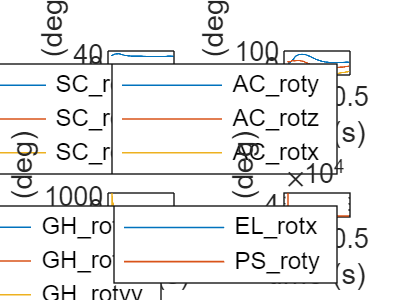


t = 0;
%tend = 0.5;
%tstep = .003;
%nsteps = round((tend-t)/tstep);

filename = 'C:\Users\s202421\Desktop\DAS\ComputedMuscleControl\one_controls.sto';
[data, C, tableData] = readMOTSTOTRCfiles('C:\Users\s202421\Desktop\DAS\ComputedMuscleControl\one\', 'one_controls.sto');

times = data(:,1);
times(end+1,1) = data(end,1);
u_recorded = data(:,2:139);
tstep = times(1);
nsteps = length(times);


%tout = tstep*(0:nsteps)';
tout = times;
xout = zeros(nsteps, nstates);
uout = zeros(nsteps, 138);
mfout = zeros(nsteps, 138);

% Load equilbrium state x
load('equilibrium.mat');
% Run simulation
xout(1,:) = x';
% Initialize variables
step_u = zeros(nmus,1);
step_xdot = zeros(nstates,1);    

tic
deltoid_scap =37:1:46;
muscles = zeros(138,1);
muscles(deltoid_scap) = 1;


for i=1:(nsteps-1)
    %u = muscles;
    u = u_recorded(i,:)';
    %u = stimfun(t,deltoid_scap);
    
    % Advance simulation by a step
    [x, step_xdot, step_u] = das3step(x, u, tstep, step_xdot, step_u);
    mf = das3('Muscleforces',x);
    xout(i+1,:) = x';   % store result
    uout(i+1,:) = u';
    mfout(i+1,:) = mf';

    %t = t + tstep;
    t = times(i);
    tstep = times(i+1)-times(i);
end
simtime = toc;

% Plots on screen
plotangles(tout,xout);

clc;
clear; 
% Some model related variables
modelparams = load('model_struct'); 
model = modelparams.model;

ndof = model.nDofs;
nmus = model.nMus;
nstates = 2*ndof + 2*nmus;

% Initialize the model
das3('Initialize',model);

*****************************************************
*                      DAS3MEX                      *
*  (c) 2010-2012 Case Western Reserve University    *
*****************************************************
Initializing...


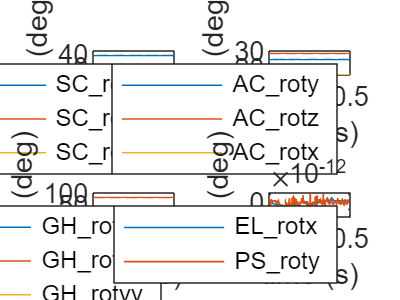


t = 0;
tend = 0.5;
tstep = .003;
nsteps = round((tend-t)/tstep);

tout = tstep*(0:nsteps)';
xout = zeros(nsteps+1, nstates);
uout = zeros(nsteps+1, 138);
mfout = zeros(nsteps+1, 138);

% Load equilbrium state x
load('equilibrium.mat');
% Run simulation
xout(1,:) = x';
% Initialize variables
step_u = zeros(nmus,1);
step_xdot = zeros(nstates,1);    

tic
for i=1:(nsteps)
    u = zeros(nmus,1);
    
    % Advance simulation by a step
    [x, step_xdot, step_u] = das3step(x, u, tstep, step_xdot, step_u);
    mf = das3('Muscleforces',x);
    xout(i+1,:) = x';   % store result
    uout(i+1,:) = u';
    mfout(i+1,:) = mf';

    t = t + tstep;

end
simtime = toc;

% Plots on screen
plotangles(tout,xout);

% Report computation time on the screen
fprintf('CPU time per time step: %8.3f ms\n', 1000*simtime/nsteps);
fprintf('Simulation speed is %8.3f times faster than real time\n',tend/simtime);


% Find DOF names
dofnames = cell(ndof,1);
for idof=1:ndof
    dofnames{idof} = model.dofs{idof}.osim_name;
end

% Export to mat file and to opensim motion file
save('simulation_zero_eq_position','tout','xout');
make_osimm('simulation_zero_eq_position', dofnames, xout(:,1:ndof), tout);
disp('Simulation result has been saved in simulation.mat');

Simulation result has been saved in simulation.mat


disp('Simulated motion has been saved in simulation.sto');

Simulated motion has been saved in simulation.sto
